clear all;
file = readtable('Dataset.csv','PreserveVariableNames',true)

file = 25741×15 table
    Priority    Unix TimeStamp    Source port    Destination port    Protocol      TTL       TOS    Datagram Length    A    P    R    S    F    TCP length    TCP options
    ________    ______________    ___________    ________________    ________    ________    ___    _______________    _    _    _    _    _    __________    ___________

       3                 -1         0.76349          -0.99924           3        -0.50598     1              -1        0    0  

file = table2array(file);
labels = readtable('Published/Classes.csv','PreserveVariableNames',true);
labels = table2array(labels);

sigma = cov(file)

sigma =     0.6853   -0.0446   -0.1769    0.0593    0.0253   -0.0194   -0.0224   -0.0061   -0.1063   -0.1094    0.0581    0.0020    0.0215   -0.3474   -0.3002
   -0.0446    0.2712   -0.0871   -0.0280   -0.0641   -0.0040    0.1320   -0.0245   -0.0220    0.0205   -0.0322   -0.0019   -0.0128   -0.2146   -0.1592
   -0.1769   -0.0871    0.4518   -0.0593    0.0384   -0.0288   -0.1375   -0.0273    0.1009    0.1502    0.0120   -0.0000   -0.0217    0.7076    0.5941
    0.0593   -0.0280   -0.0593    0.0830    0.0017    0.0069   -0.0097   -0.0075    0.0031    0.0052    0.0021    0.0010    0.0241    0.0338    0.0287
    0.0253   -0.0641    0.0384    0.0017    0.0965    0.0486   -0.1190    0.0162    0.0272    0.0223    0.0016    0.0001    0.0007    0.0960    0.0670
   -0.0194   -0.0040   -0.0288    0.0069    0.0486    0.1533   -0.0002    0.0282    0.0309    0.0180   -0.0060   -0.0007    0.0044   -0.2132   -0.2375
   -0.0224    0.1320   -0.1375   -0.0097   -0.1190   -0.0002    0.2739   -0.0206   -0.

mu = mean(file);

class0_ind = find(labels==0);
class1_ind = find(labels==1);

**Feature extraction using : PCA**

[E1,v1] = eig(sigma);
features_inf = max(v1);

[E2,v2] = eigs(sigma);

pca_data = file*E2(:,1:2)

pca_data =     0.5251   -2.9997
    0.1507   -3.3948
    0.1507   -3.3948
    4.2705   -3.7407
    4.3948   -3.6326
    7.1832   -3.6852
    6.9222   -4.0375
    4.6445   -3.3066
    4.7698   -3.1971
    4.2718   -3.7287


pca_0 = pca_data(class0_ind,:);

pca_1 = pca_data(class1_ind,:);

tcp_opt = pca_data(:,1)

tcp_opt =     0.5251
    0.1507
    0.1507
    4.2705
    4.3948
    7.1832
    6.9222
    4.6445
    4.7698
    4.2718


tcp_len = pca_data(:,2)

tcp_len =    -2.9997
   -3.3948
   -3.3948
   -3.7407
   -3.6326
   -3.6852
   -4.0375
   -3.3066
   -3.1971
   -3.7287


% scatter3(pca_0(:,1),pca_0(:,2),pca_0(:,3),'Marker',"*")
% xlabel('Flag - F')
% hold on 
% scatter3(pca_1(:,1),pca_1(:,2),pca_1(:,3),'Marker','.')
% ylabel('TCP options')
% xlabel('TCP length')
% hold off

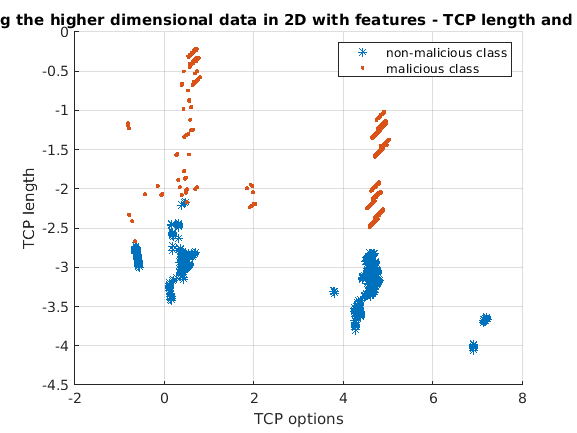

scatter(pca_0(:,1),pca_0(:,2),'MarkerFaceColor',[1 1 0],'Marker',"*")
hold on 
scatter(pca_1(:,1),pca_1(:,2),'MarkerFaceColor',[0 0 0],'Marker','.')
title('Visualizing the higher dimensional data in 2D with features - TCP length and TCP options')
xlabel('TCP options')
ylabel('TCP length')
hold off
legend('non-malicious class','malicious class')
grid on 

pca_data = file*E2(:,1:3)

pca_data =     0.5251   -2.9997    0.6227
    0.1507   -3.3948   -0.0354
    0.1507   -3.3948   -0.0354
    4.2705   -3.7407   -0.9165
    4.3948   -3.6326   -0.8751
    7.1832   -3.6852   -0.9660
    6.9222   -4.0375   -1.5007
    4.6445   -3.3066   -0.2372
    4.7698   -3.1971   -0.2146
    4.2718   -3.7287   -0.9068


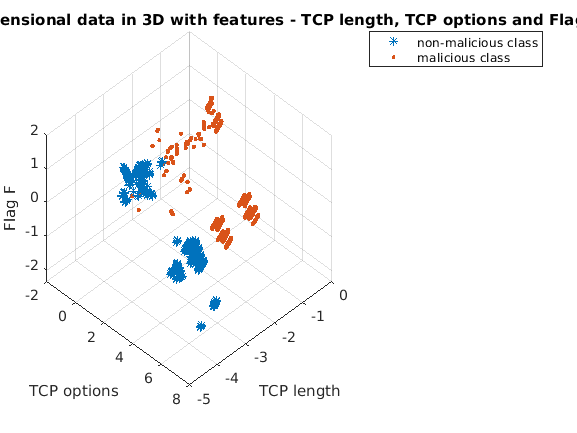

pca_0 = pca_data(class0_ind,:);

pca_1 = pca_data(class1_ind,:);

scatter3(pca_0(:,1),pca_0(:,2),pca_0(:,3),'MarkerFaceColor',[1 1 0],'Marker',"*")
hold on 
scatter3(pca_1(:,1),pca_1(:,2),pca_1(:,3),'MarkerFaceColor',[0 0 0],'Marker','.')
title('Visualizing the higher dimensional data in 3D with features - TCP length, TCP options and Flag F')
xlabel('TCP options')
ylabel('TCP length')
zlabel('Flag F')
hold off
grid on 
view([45,45])
legend('non-malicious class','malicious class')

% % scatter(class0_ind,pca_0,'Marker',"*")
% % hold on 
% % scatter(class1_ind,pca_1,'Marker',".")
% % hold off

% X = bsxfun(@minus,file,mean(file));
% [coeff,score,latent] = pca(X)
% 
% [V,D] = eig(cov(X));
% 
% dataInPrincipalComponentSpace = X*coeff(:,1:2)
% score
% % The columns of X*coeff are orthogonal to each other. This is shown with ...
% corrcoef(dataInPrincipalComponentSpace)
% % The variances of these vectors are the eigenvalues of the covariance matrix, and are also the output "latent". Compare
% % these three outputs
% var(dataInPrincipalComponentSpace)'
% latent
% sort(diag(D),'descend')

% data_0 = dataInPrincipalComponentSpace(class0_ind,:);
% data_1 = dataInPrincipalComponentSpace(class1_ind,:)
% scatter(data_0(:,1),data_0(:,2))
% hold on 
% scatter(data_1(:,1),data_1(:,2))
% hold off

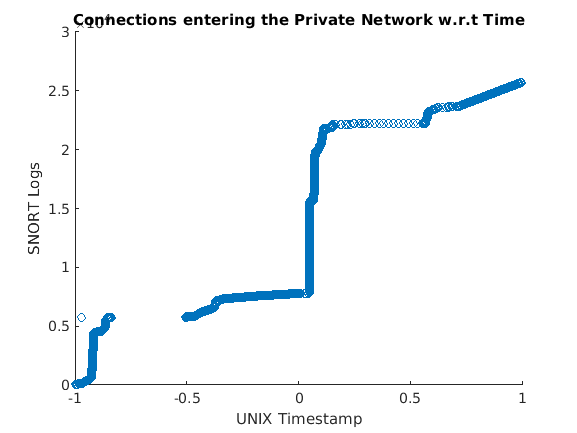

scatter(file(:,2),[1:length(file(:,2))])
xlabel('UNIX Timestamp')
ylabel('SNORT Logs')
title('Connections entering the Private Network w.r.t Time')

features_inf;
t = sum(features_inf);
features_p = 100*features_inf.'/t

features_p =     0.0018
    0.0410
    0.0611
    0.1570
    0.1851
    0.2360
    0.7172
    0.7930
    1.3978
    1.8793


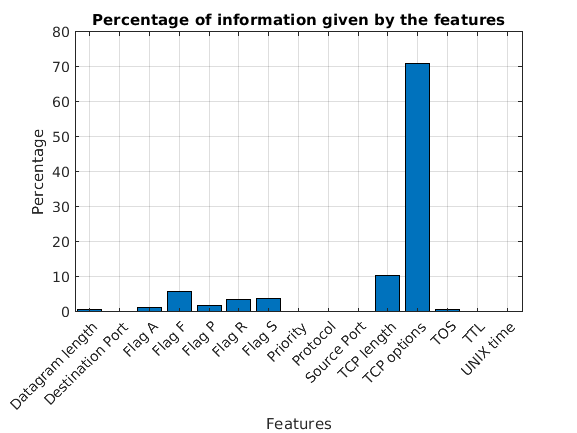


f_name  = categorical({'Priority','UNIX time', 'Source Port', 'Destination Port','Protocol','TTL','TOS','Datagram length', 'Flag A','Flag P', 'Flag R','Flag S', 'Flag F','TCP length','TCP options'});
bar(f_name,features_p)
title('Percentage of information given by the features')
xlabel('Features')
ylabel('Percentage')
grid on